# Aero 2: 1 DOF Pitch Parameter Estimation

The equation of motion of the AERO for the 1 DOF pitch-only system is


$$J_p\ddot{\theta} + D_p{\dot{\theta}} + K_{sp}\theta = \tau_p=K_{pp} D_t \omega_m(t)$$


where $\theta$ is the pitch angle, $J_p$ is the equivalent moment of inertia acting about the pitch axis, $D_p$ is the viscous damping, $K_{sp}$ is the stiffness, $K_{pp}$ is the force thrust gain, $D_t$ is the distance from the pivot point to the propeller, and $\omega_m$ is the rotor propeller speed. 

The corresponding open-loop transfer function is a second-order transfer function


$$P(s) = \frac{\Theta(s)}{\Omega_m(s)} = \frac{ \frac{D_tK_{pp}}{J_p} } {s^2 + \frac{D_p}{J_p}s + \frac{K_{sp}}{J_p}}$$


## Running the Experiment

Apply a step voltage to the front rotor and then set it to 0V to see the free-oscillation response. Measure the damping, $D_p$, and stiffness, $K_{sp}$, from the free-oscillation response and the thrust, $K_{pp}$, from the step response.

### Aero 2 Configuration

- **Unlock** the pitch axis and **lock **the yaw axis.

- Back rotor is **horizontal **and front rotor is **horizontal**.

- Mount weight on each rotor.

Run the model in QUARC to get new data.

% Load Simulink model
open("q_aero2_pitch_step.slx");

Plot results

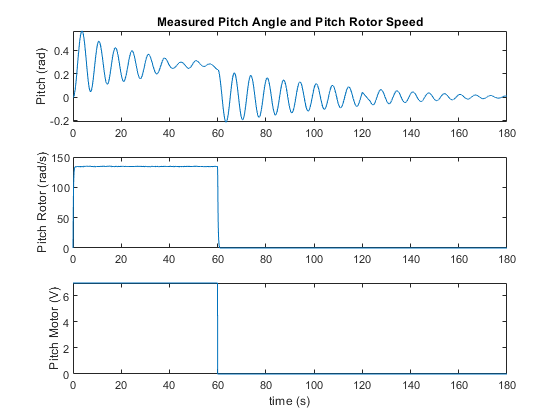

% Load measured data from past run
load('DataPitchStep.mat');
% store in variables
t = DataPitchStep(1,:);  % time (s)
Vp = DataPitchStep(2,:);  % pitch voltage (V))
wm_p = DataPitchStep(3,:); % rotor speed (rad/s)
theta = DataPitchStep(4,:); % pitch angle (rad)
%
subplot(3,1,1);
plot(t,theta);
title('Measured Pitch Angle and Pitch Rotor Speed');
ylabel('Pitch (rad)');
subplot(3,1,2);
plot(t,wm_p);
ylabel('Pitch Rotor (rad/s)');
subplot(3,1,3);
plot(t,Vp);

ylabel('Pitch Motor (V)');
xlabel('time (s)');

### Find the Pitch Stiffness and Damping

Find natural frequency and damping ratio of the free-oscillation response.

Load Aero 2 Parameters.

aero2_parameters;

**Student Exercise**: Enter the measured peak amplitude and time of the 1st and nth oscillations.

% Measure first overshoot
% O1 = ;
% t1 = ;
% Measure nth overshoot (s)
% n = ;
% On = ;
% tn = ;
%
% Oscillation period (s)
Tosc = (tn-t1) / (n-1);
% Decrement (i.e., subsidence) ratio
sigma = 1/n*log(O1/On);
% Damping ratio
% zeta = 
% Undamped natural frequency (rad/s)
% wn = 

Calculate siffness and damping based on measured response.

**Student Exercise: **Enter the equation to find the parameters

% Stiffness (N.m/rad)
% Ksp = 
% Damping (N.m/(rad/s))
% Dp = 

### Finding the Thrust

Applying a step input to the pitch rotor speed with an amplitude of $\omega_0$, 


$$\Theta(s)= \frac{ \frac{D_tK_{pp}}{J_p} } {s^2 + \frac{D_p}{J_p}s + \frac{K_{sp}}{J_p}
}\frac{\omega_0}{s}$$


The steady-state angle of this is


$$\theta_{ss} = \frac{D_tK_{pp}}{K_{sp}}\omega_0$$


Solving for the thrust


$$K_{pp} = \frac{\theta_{ss}K_{sp}}{D_t\omega_0}$$


Find pitch thrust from step response

**Student Exercise**: 

- Enter the measured steady-state angle of the step response and the input rotor speed. 

- Enter the equation to find the thrust force gain.

% Steady-state pitch angle at end of step input 120 sec (rad)
% theta_ss = ;
% Rotor speed at same time (rad/s)
% wm0 = ;
% Pitch thrust gain (N/(rad/s))
% Kpp = 

## Model Validation

Open the following Simulink model and run it in QUARC to validate that the model you derived matches with the hardware. 

open("q_aero2_pitch_model_val.slx")

Plot results

% load saved data
load("DataPitchModelVal.mat");
t = DataPitchModelVal(1,:); % time (s)
Vp = DataPitchModelVal(2,:); % pitch rotor voltage (V)
wm = DataPitchModelVal(3,:); % rotor speed (rad/s)
theta_meas = DataPitchModelVal(4,:); % pitch angle - measured from hardware
theta_sim =DataPitchModelVal(5,:); % pitch angle - model
%
subplot(3,1,1);
plot(t,theta_meas,t,theta_sim);
title('Pitch Model Validation');
ylabel('Pitch (rad)');
subplot(3,1,2);
plot(t,wm);
ylabel('Pitch Rotor (rad/s)');
subplot(3,1,3);
plot(t,Vp);
ylabel('Pitch Motor (V)');
xlabel('time (s)');